# Touchdown Trajectory

clear; close all; clc;

## Find x_foot(t)

syms t
P = [-0.2,-0.259,-0.275,-0.384, 0.261,-0.017, 0.248, 0.267, 0.259, 0.2];
n = length(P)-1;
T = t;
y = 0;
for i = 0:n
    y = y + (nchoosek(n,i)*((1-T)^(n-i))*(T^(i))*P(i+1));
end

## Find x_dot(t)

x_dot = diff(y,t) 

$$x\_dot = \frac{144\,t\,{\left(t-1\right)}^{7}}{125}-\frac{531\,{\left(t-1\right)}^{8}}{1000}+\frac{2403\,t^{7}\,\left(2\,t-2\right)}{250}-\frac{259\,t^{7}\,\left(9\,t-9\right)}{125}-\frac{6867\,t^{2}\,{\left(t-1\right)}^{6}}{250}-\frac{8127\,t^{3}\,{\left(t-1\right)}^{5}}{25}-\frac{8757\,t^{4}\,{\left(t-1\right)}^{4}}{50}-\frac{3339\,t^{5}\,{\left(t-1\right)}^{3}}{25}+\frac{1197\,t^{6}\,{\left(t-1\right)}^{2}}{250}-\frac{531\,t^{8}}{1000}$$

x_dot_o = double(subs(x_dot,t,0))

x_dot_o = -0.5310

x_dot_f = double(subs(x_dot,t,1))

x_dot_f = -0.5310

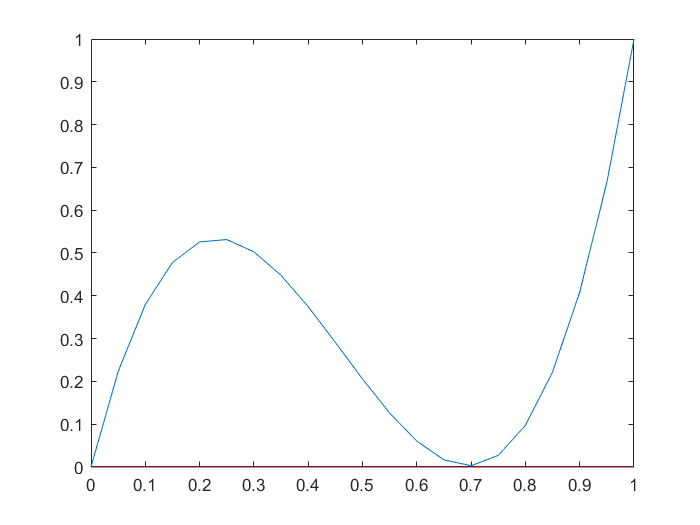


beta = [0, (1/3)*-2.75/x_dot_o, 1-((1/3)*-4/x_dot_f), 1];
tau = 0:0.05:1;
z = bezier(beta,tau);

figure;
plot(tau,z);

n = length(beta)-1;
T_mod = 0;
for i = 0:n
    T_mod = T_mod + (nchoosek(n,i)*((1-T)^(n-i))*(T^(i))*beta(i+1));
end

s_dot = diff(T_mod,t)

$$s\_dot = \frac{2750\,t\,\left(2\,t-2\right)}{531}+\frac{4814\,t\,\left(3\,t-3\right)}{1593}+\frac{2750\,{\left(t-1\right)}^{2}}{531}+\frac{4000\,t^{2}}{531}$$


s_dot_o = double(subs(s_dot,t,0))

s_dot_o = 5.1789

s_dot_f = double(subs(s_dot,t,1))

s_dot_f = 7.5330


x_dot_ds = subs(x_dot,t,T_mod); 

test = double(subs(x_dot_ds,t,0))*s_dot_o

test = -2.7500

test_2  = double(subs(x_dot_ds,t,1))*s_dot_f

test_2 = -4